% (sin(y)+(1-y)*cos(x))*dx+((1+x)*cos(y)-sin(x))*dy=0

% 1)
clear
% y'=-(sin(y)+(1-y)*cos(x))/((1+x)*cos(y)-sin(x))
syms x y(x) C
eqn=diff(y(x))==-(sin(y)+(1-y)*cos(x))/((1+x)*cos(y)-sin(x))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=\frac{\sin\left(y\left(x\right)\right)-\cos\left(x\right)\,\left(y\left(x\right)-1\right)}{\sin\left(x\right)-\cos\left(y\left(x\right)\right)\,\left(x+1\right)}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(C_{11}+\sin\left(y\right)-\sin\left(x\right)\,\left(y-1\right)+x\,\sin\left(y\right),y\right)$$

% solve(sin(y) - sin(x)*(y - 1) + x*sin(y) == -C8, y)
eq1= sin(y) - sin(x)*(y - 1) + x*sin(y) == C

$$eq1(x) = \sin\left(y\left(x\right)\right)+x\,\sin\left(y\left(x\right)\right)-\sin\left(x\right)\,\left(y\left(x\right)-1\right)=C$$


% 2)
syms x y
P(x,y)=sin(y)+(1-y)*cos(x)

$$P(x, y) = \sin\left(y\right)-\cos\left(x\right)\,\left(y-1\right)$$

Q(x,y)=(1+x)*cos(y)-sin(x)

$$Q(x, y) = \cos\left(y\right)\,\left(x+1\right)-\sin\left(x\right)$$

chk1=diff(P,y)-diff(Q,x)

$$chk1(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = C\left(y\right)-\sin\left(x\right)\,\left(y-1\right)+x\,\sin\left(y\right)$$

% C(y) - sin(x)*(y - 1) + x*sin(y)
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)-\sin\left(x\right)+x\,\cos\left(y\right)$$

% diff(C(y), y) - sin(x) + x*cos(y)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)-\cos\left(y\right)$$

% diff(C(y), y) - cos(y)
C(y)=int(cos(y),y)

$$C(y) = \sin\left(y\right)$$

% sin(y)
% sin(y) - sin(x)*(y - 1) + x*sin(y) = C1

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = \sin\left(x\right)+\sin\left(y\right)+x\,\sin\left(y\right)-y\,\sin\left(x\right)$$

syms C
eq2=U==C

$$eq2 = \sin\left(x\right)+\sin\left(y\right)+x\,\sin\left(y\right)-y\,\sin\left(x\right)=C$$

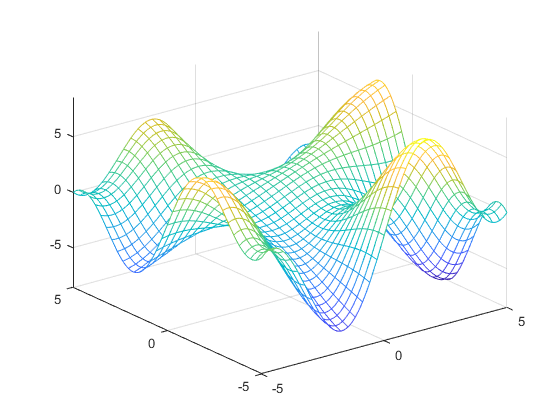

fmesh(U)